## 程序说明

% 本程序用于求解光场中粒子的受力
% 计算方法与公式保持完全一致

% lusen
% 2023/09/104 18:14

## 数据载入及预处理

% 数据载入
clc;clear;close all;

% ================ 不同配置的影响 ================
% load field_data_10.mat % 金属表面上方 10nm 位置 斯格明子

% load field_data_10_noAg.mat % 同位置处仅光源和玻璃存在的情况，监视器与skyrmion相同
% load field_NoAg_glass10.mat % 同位置处仅光源和玻璃存在的情况，监视器在玻璃上方10nm

% load field_data_10_noGlassAg.mat % 仅光源，监视器位置同斯格明子
% load field_NoAgGlass_m200.mat % 仅光源，监视器在-200nm
% load field_NoAgGlass_p180.mat % 仅光源，监视器在+180nm
% load field_NoAgGlass_p580.mat % 仅光源，监视器在+580nm

% ============== 偏振与拓扑荷的影响 ===============
load field_data_n1m_1.mat % n 代表光束偏振 m 代表涡旋拓扑荷 斯格明子
% load field_data_n1m1.mat
% load field_data_n_1m_1.mat
% load field_data_n_1m1.mat % 斯格明子

% ================== 涡旋的影响 ===================
% load field_data_vor_n_1m0.mat % 不加涡旋
% load field_data_vor_n_1m1.mat % 斯格明子
% load field_data_vor_n_1m2.mat
% load field_data_vor_n_1m3.mat
% load field_data_vor_n_1m4.mat
% load field_data_vor_n_1m5.mat

% 矩阵转置
Ex1=Ex1.';
Ey1=Ey1.';
Ez1=Ez1.';
Hx1=Hx1.';
Hy1=Hy1.';
Hz1=Hz1.';

## 初始化参数

% 电磁场与材料数据
lamda = 632.8e-9; % wavelength
k0 = 2*pi/lamda; % k=2*pi/lamda;wavevector

epsilon0 = 8.8542e-12;
mu0 = 1.2566e-6;
c = 3e8; % light speed in vacuum
omega = (2*pi*c)/lamda; % light angle frequency

n1 = 1; % surrounding referactive
epsilon1 = n1^2; % surrounding permittivity
mu1 = 1; % surrounding permeability
epsilon2 = 2.5+0.5*1i;
% epsilon2=2+0.4*1i;
mu2 = 1;
k1 = n1*omega/c; % wave number in surrounding material

% nano particle parameters
radius = 20e-9; % particle radius
kappa = 0.2+0.6*1i;  % chiral parameter
% kappa = 0.2-0.6*1i;  % chiral parameter
% kappa=0.2;  % achiral parameter

% 工程参数
scale = 10e-9; % 坐标系步长，网格精度缩放因子，用于梯度求解
sampling_point = size(Ex1,1); % 采样点数,或称电磁场数据的尺寸
center_sweep_line = (1+sampling_point)/2; % 用于确定数组的中心行，以方便提取中心行数据

xaxis = linspace(-1,1,sampling_point); % 导入origin作为x轴

source_power=7.63109e-13; % FDTD光功率
amp_coef = 0.1/source_power*1e12; % 功率转换系数，皮牛
% amp_coef = 1; % 功率转换系数，皮牛

## 计算米氏散射系数

球形粒子的米氏散射系数：


$$\[\begin{array}{l}
{a_n} = \frac{{V_n^RA_n^L + V_n^LA_n^R}}{{W_n^LV_n^R + W_n^RV_n^L}},\\
{b_n} = \frac{{W_n^LB_n^R + W_n^RB_n^L}}{{W_n^LV_n^R + W_n^RV_n^L}},\\
{c_n} = i\frac{{W_n^RA_n^L - W_n^LA_n^R}}{{W_n^LV_n^R + W_n^RV_n^L}}.
\end{array}\]$$


令J代表L或R：


$$$\begin{array}{l}
W_n^{\left( J \right)} = q{\psi _n}\left( {{q_J}x} \right)\xi _n^{'}\left( x \right) - \xi \left( x \right)\psi _n^{'}\left( {{q_J}x} \right),\\
V_n^{\left( J \right)} = {\psi _n}\left( {{q_J}x} \right)\xi _n^{'}\left( x \right) - q\xi \left( x \right)\psi _n^{'}\left( {{q_J}x} \right),\\
A_n^{\left( J \right)} = q{\psi _n}\left( {{q_J}x} \right)\psi _n^{'}\left( x \right) - {\psi _n}\left( x \right)\psi _n^{'}\left( {{q_J}x} \right),\\
B_n^{\left( J \right)} = {\psi _n}\left( {{q_J}x} \right)\psi _n^{'}\left( x \right) - q{\psi _n}\left( x \right)\psi _n^{'}\left( {{q_J}x} \right).
\end{array}$$$


Here, $$x = {k_1}a$$, $${\psi _n}\left( s \right) = s{j_n}\left( s \right)$$,$$\xi \left( s \right) = sh_n^{\left( 1 \right)}\left( s \right)$$ , where  $${j_n}\left( s \right)$$ and $$h_n^{\left( 1 \right)}\left( s \right)$$ 是第一类球贝塞尔函数和汉克尔函数。一阶第一类球贝塞尔函数 $$j_ { 1 } \left( x \right) = \frac { s i n x } { x ^ { 2 } } - \frac { c o s x } { x }$$ ，一阶第二类表示为 $$y _ { 1 } \left( x \right) = \ j_{- 2 }\left( x \right) = - \frac { c o s x } { x ^ { 2 } } - \frac { s i n x } { x }$$，一阶球汉克尔函数为 $$h _ n ^ {( 1 )} \left( x \right) = j _ { n } \left( x \right) + i y _ { n } \left( x \right)$$

q 被定义为平均折射率，$$q=(q_L+q_R)/2$$，其中$$q _ { L } = \left( \sqrt { \epsilon _ { 2 } \mu_ { 2 } } + \kappa \right) / \sqrt {\epsilon _ { 1 } \mu _ { 1 } }$$，$$q _ { R } = \left( \sqrt { \epsilon _ { 2 } \mu_ { 2 } } - \kappa \right) / \sqrt {\epsilon _ { 1 } \mu _ { 1 } }$$

qL=((epsilon2*mu2)^0.5+kappa)/((epsilon1*mu1)^0.5);
qR=((epsilon2*mu2)^0.5-kappa)/((epsilon1*mu1)^0.5);
qavg=(qL+qR)/2;

X=k1*radius; % variation;
Z1=qL*X;
Z2=qR*X;
Z3=X;
nu=1;

syms x;
Psi(x)=(sin(x)-x*cos(x))/x; % 用到一阶第一类球贝塞尔函数
Psi1(x)=(x*cos(x)-sin(x)+x^2*sin(x))/ x^2; % 后面有1的代表求导
Xi(x)=x*(besselj(nu,x)+1i*bessely(nu,x)); % 用到一阶球汉克尔函数
Xi1(x)=diff(Xi(x));

W1L=qavg*Psi(Z1)*Xi1(Z3)-Xi(Z3)*Psi1(Z1);
V1L=Psi(Z1)*Xi1(Z3)-qavg*Xi(Z3)*Psi1(Z1);
A1L=qavg*Psi(Z1)*Psi1(Z3)-Psi(Z3)*Psi1(Z1);
B1L=Psi(Z1)*Psi1(Z3)-qavg*Psi(Z3)*Psi1(Z1);

W1R=qavg*Psi(Z2)*Xi1(Z3)-Xi(Z3)*Psi1(Z2);
V1R=Psi(Z2)*Xi1(Z3)-qavg*Xi(Z3)*Psi1(Z2);
A1R=qavg*Psi(Z2)*Psi1(Z3)-Psi(Z3)*Psi1(Z2);
B1R=Psi(Z2)*Psi1(Z3)-qavg*Psi(Z3)*Psi1(Z2);

an=(V1R*A1L+V1L*A1R)/(W1L*V1R+W1R*V1L);
bn=(W1L*B1R+W1R*B1L)/(W1L*V1R+W1R*V1L);
cn=1i*(W1R*A1L-W1L*A1R)/(W1L*V1R+W1R*V1L);

a1=eval(an); % 计算表达式的值
b1=eval(bn);
c1=eval(cn);

## 计算交叉项


$$${\alpha _{ee}} = i\frac{{6\pi {\varepsilon _1}{\varepsilon _0}}}{{k_1^3}}{a_1},{\rm{ }}{\alpha _{mm}} = i\frac{{6\pi {\mu _1}{\mu _0}}}{{k_1^3}}{b_1},{\rm{ }}{\alpha _{em}} = \frac{{6\pi {n_1}}}{{ck_1^3}}{c_1}$$$


arfaee=1i*((6*pi*epsilon1*epsilon0*a1)/k1^3); % alpha_ee
arfamm=1i*((6*pi*mu1*mu0*b1)/k1^3);
arfaem=((6*pi*n1*c1)/(c*k1^3)); 


$$${\sigma _e} = \left( {{k_1}/{\varepsilon _1}{\varepsilon _0}} \right)*{\mathop{\rm Im}\nolimits} \left( {{\alpha _{ee}}} \right)$$$
 


$$${\rm{ }}{\sigma _m} = \left( {{k_1}/{\mu _1}{\mu _0}} \right)*{\mathop{\rm Im}\nolimits} \left( {{\alpha _{mm}}} \right)$$$



$$$\sigma  = {\sigma _e} + {\sigma _m} - \left( {{c^2}k_1^4/6\pi n_1^2} \right)*\left( {{\mathop{\rm Re}\nolimits} \left( {{\alpha _{ee}}\alpha _{mm}^ * } \right) + {{ {{\alpha _{em}\alpha _{em}^*}} }}} \right)$$$


sigmaee=(k1/(epsilon1*epsilon0))*imag(arfaee);
sigmamm=(k1/(mu1*mu0))*imag(arfamm);
sigma=sigmaee+sigmamm-((c^2*k1^4)/(6*pi*n1^2))*(real(arfaee*conj(arfamm))+arfaem*conj(arfaem));


$$${\gamma _e} = 2w{\mathop{\rm Im}\nolimits} \left[ {{\alpha _{em}}} \right] - \left( {ck_1^4/3\pi {\varepsilon _1}{\varepsilon _0}{n_1}} \right) * {\mathop{\rm Re}\nolimits} \left( {{\alpha _{ee}}\alpha _{em}^ * } \right)$$$



$$${\gamma _m} = 2w{\mathop{\rm Im}\nolimits} \left[ {{\alpha _{em}}} \right] - \left( {ck_1^4/3\pi {\mu _1}{\mu _0}{n_1}} \right) * {\mathop{\rm Re}\nolimits} \left( {{\alpha _{mm}}\alpha _{em}^ * } \right)$$$


gamaee=2*omega*imag(arfaem)-((c*k1^4)/(3*pi*epsilon1*epsilon0*n1))*real(arfaee*conj(arfaem));
gamamm=2*omega*imag(arfaem)-((c*k1^4)/(3*pi*mu1*mu0*n1))*real(arfamm*conj(arfaem));


$$$\left\langle S \right\rangle  = {\mathop{\rm Re}\nolimits} \left( {E \times {H^ * }} \right)/2$$$


% the time-averaged Poynting vector
Poyx=0.5*real(Ey1.*conj(Hz1)-conj(Hy1).*Ez1);
Poyy=0.5*real(Ez1.*conj(Hx1)-conj(Hz1).*Ex1);
Poyz=0.5*real(Ex1.*conj(Hy1)-conj(Hx1).*Ey1);


$$$\left\langle {{L_e}} \right\rangle  = \left( { - {\varepsilon _1}{\varepsilon _0}/4w} \right)*{\mathop{\rm Im}\nolimits} \left( {E \times {E^ * }} \right)$$$



$$$\left\langle {{L_m}} \right\rangle  = \left( { - {\mu _1}{\mu _0}/4w} \right)*{\mathop{\rm Im}\nolimits} \left( {H \times {H^ * }} \right)$$$


% SAM densities
Lex=(-(epsilon1*epsilon0)/(4*omega))*imag(Ey1.*conj(Ez1)-conj(Ey1).*Ez1); % 叉积运算
Ley=(-(epsilon1*epsilon0)/(4*omega))*imag(Ez1.*conj(Ex1)-conj(Ez1).*Ex1);
Lez=(-(epsilon1*epsilon0)/(4*omega))*imag(Ex1.*conj(Ey1)-conj(Ex1).*Ey1);

Lhx=(-(mu1*mu0)/(4*omega))*imag(Hy1.*conj(Hz1)-conj(Hy1).*Hz1); % 叉积运算
Lhy=(-(mu1*mu0)/(4*omega))*imag(Hz1.*conj(Hx1)-conj(Hz1).*Hx1);
Lhz=(-(mu1*mu0)/(4*omega))*imag(Hx1.*conj(Hy1)-conj(Hx1).*Hy1);


$$$\left. \begin{array} { l } { \left \langle U\right \rangle = \frac { 1 } { 4 } R e [ \alpha _ { ee } ] |E| ^ { 2 } + \frac { 1 } { 4 } R e [ \alpha _ { mm}] |H | ^ { 2 } }  { + \frac { 1 } { 2 } R e [ \alpha _ { em } ] Im[E \cdot H ^ { * } ] } \end{array} \right.$$$


% optical potential
modeEx=abs(Ex1);modeEy=abs(Ey1);modeEz=abs(Ez1);% 计算电磁场分量的模
modeHx=abs(Hx1);modeHy=abs(Hy1);modeHz=abs(Hz1);
modeE1=sqrt(modeEx.^2+modeEy.^2+modeEz.^2); % 电场模
modeH1=sqrt(modeHx.^2+modeHy.^2+modeHz.^2); % 磁场模
k13=0.5*real(arfaem).*imag(Ex1.*conj(Hx1)+Ey1.*conj(Hy1)+Ez1.*conj(Hz1));
U1=0.25*real(arfaee).*modeE1.^2+0.25*real(arfamm).*modeH1.^2+k13; % 第一平面的U分量

备注：由公式知道U由三部分组成，若U的每一项都考虑，则y方向的力会增加一个梯度力项，故不应该考虑2、3项，

经过测试，y方向的梯度力仅与第三项有关。

## 计算光学力


$$\[\begin{array}{c}
\left\langle F \right\rangle  = \nabla \left\langle U \right\rangle  + \frac{{\sigma {n_1}}}{c}\left\langle S \right\rangle  - {\mathop{\rm Im}\nolimits} \left( {{\alpha _{em}}} \right)\nabla  \times \left\langle S \right\rangle  - \frac{{c{\sigma _e}}}{{{n_1}}}\nabla  \times \left\langle {{L_e}} \right\rangle  - \frac{{c{\sigma _m}}}{{{n_1}}}\nabla  \times \left\langle {{L_m}} \right\rangle  + w{\gamma _e}\left\langle {{L_e}} \right\rangle  + w{\gamma _m}\left\langle {{L_m}} \right\rangle  + \frac{{ck_1^4}}{{12\pi {n_1}}}{\mathop{\rm Im}\nolimits} \left( {{\alpha _e}\alpha _m^ * } \right){\mathop{\rm Im}\nolimits} \left( {E \times {H^ * }} \right)
\end{array}\]$$


% 第 1 项
% the first term corresponds to the gradient force Fgrad 
% due to the particle-field interaction;
[ux,uy]=gradient(U1,scale,scale);
Ux=ux;
Uy=uy; % Uy=uy;由于matlab坐标系问题，y 轴数据需要要取反
F_gradx = amp_coef*Ux;
F_grady = amp_coef*Uy;


% 第 2 项
% the radiation pressure Frad
% proportional to the time-averaged Poynting vector
Sx=(sigma*n1/c)*Poyx;
Sy=(sigma*n1/c)*Poyy;
Sz=(sigma*n1/c)*Poyz;
F_radx = amp_coef*Sx;
F_rady = amp_coef*Sy;
F_radz = amp_coef*Sz;

% 第 3 项
% the "vortex" force Fvor determined by the energy flow vortex 
% (the curl of the Poynting vector) and particle chirality (aem)
[x1,y1]=gradient(Poyx,scale,scale);
[x2,y2]=gradient(Poyy,scale,scale);
[x3,y3]=gradient(Poyz,scale,scale);
CurlPoyx=imag(arfaem)*(y3-0);
CurlPoyy=imag(arfaem)*(0-x3);
CurlPoyz=imag(arfaem)*(x2-y1);
F_vorx = -amp_coef*CurlPoyx;
F_vory = -amp_coef*CurlPoyy;
F_vorz = -amp_coef*CurlPoyz;

% 第 4、5 项
% the curl-spin force Fcurl associated with the curl of the SAM densities
[x4,y4]=gradient(Lex,scale,scale);
[x5,y5]=gradient(Ley,scale,scale);
[x6,y6]=gradient(Lez,scale,scale);
CurlLex=(c*sigmaee/n1)*(y6-0);
CurlLey=(c*sigmaee/n1)*(0-x6);
CurlLez=(c*sigmaee/n1)*(x5-y4);
F_curlex = -amp_coef*CurlLex;
F_curley = -amp_coef*CurlLey;
F_curlez = -amp_coef*CurlLez;

[x7,y7]=gradient(Lhx,scale,scale);
[x8,y8]=gradient(Lhy,scale,scale);
[x9,y9]=gradient(Lhz,scale,scale);
CurlLhx=(c*sigmamm/n1)*(y9-0);
CurlLhy=(c*sigmamm/n1)*(0-x9);
CurlLhz=(c*sigmamm/n1)*(x8-y7);
F_curlhx = -amp_coef*CurlLhx;
F_curlhy = -amp_coef*CurlLhy;
F_curlhz = -amp_coef*CurlLhz;

F_curlx=F_curlex+F_curlhx;
F_curly=F_curley+F_curlhy;

% 第 6、7 项
% the spin density force Fspin related to the SAM densities
% and particle chirality (aem)
F_spinex=amp_coef*omega*gamaee*Lex;
F_spiney=amp_coef*omega*gamaee*Ley;
F_spinez=amp_coef*omega*gamaee*Lez;
F_spinmx=amp_coef*omega*gamamm*Lhx;
F_spinmy=amp_coef*omega*gamamm*Lhy;
F_spinmz=amp_coef*omega*gamamm*Lhz;

F_spinx=F_spinex+F_spinmx;
F_spiny=F_spiney+F_spinmy;
F_spinz=F_spiney+F_spinmz;

% 第 8 项，存储能量的交替流动力
F_flowx=amp_coef*(c*k1^4/(12*pi*n1))*imag(arfaee*conj(arfamm))*imag((Ey1.*conj(Hz1)-conj(Hy1).*Ez1));
F_flowy=amp_coef*(c*k1^4/(12*pi*n1))*imag(arfaee*conj(arfamm))*imag((Ez1.*conj(Hx1)-conj(Hz1).*Ex1));
F_flowz=amp_coef*(c*k1^4/(12*pi*n1))*imag(arfaee*conj(arfamm))*imag((Ex1.*conj(Hy1)-conj(Ex1).*Hy1));


$$\[\begin{array}{c}
\left\langle F \right\rangle  = \nabla \left\langle U \right\rangle  + \frac{{\sigma {n_1}}}{c}\left\langle S \right\rangle  - {\mathop{\rm Im}\nolimits} \left( {{\alpha _{em}}} \right)\nabla  \times \left\langle S \right\rangle  - \frac{{c{\sigma _e}}}{{{n_1}}}\nabla  \times \left\langle {{L_e}} \right\rangle  - \frac{{c{\sigma _m}}}{{{n_1}}}\nabla  \times \left\langle {{L_m}} \right\rangle  + w{\gamma _e}\left\langle {{L_e}} \right\rangle  + w{\gamma _m}\left\langle {{L_m}} \right\rangle  + \frac{{ck_1^4}}{{12\pi {n_1}}}{\mathop{\rm Im}\nolimits} \left( {{\alpha _e}\alpha _m^ * } \right){\mathop{\rm Im}\nolimits} \left( {E \times {H^ * }} \right)
\end{array}\]$$


% 总力
Fx=F_gradx+F_radx+F_vorx+F_curlex+F_curlhx+F_spinex+F_spinmx+F_flowx;
Fy=F_grady+F_rady+F_vory+F_curley+F_curlhy+F_spiney+F_spinmy+F_flowy;
Ftr = sqrt(Fx.^2+Fy.^2);

## 绘制图像

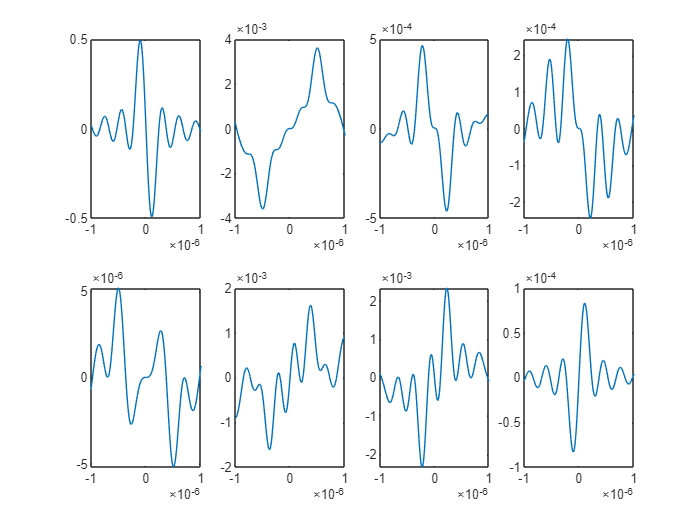

% 设置轴向范围
stepsize = linspace(-1e-6,1e-6,sampling_point);

% 散射力与自旋力
% scan_F_sca = F_sca(center_sweep_line,:);
scan_F_spinx = F_spinx(center_sweep_line,:);
scan_F_spiny = F_spiny(center_sweep_line,:);
scan_F_curlx = F_curlx(center_sweep_line,:);
scan_F_curly = F_curly(center_sweep_line,:);

% 计算并绘制 8 项力及总力（x方向）
scan_F_gradx = F_gradx(center_sweep_line,:);
scan_F_radx = F_radx(center_sweep_line,:);
scan_F_vorx = F_vorx(center_sweep_line,:);
scan_F_curlex = F_curlex(center_sweep_line,:);
scan_F_curlhx = F_curlhx(center_sweep_line,:);
scan_F_spinex = F_spinex(center_sweep_line,:);
scan_F_spinmx = F_spinmx(center_sweep_line,:);
scan_F_flowx = F_flowx(center_sweep_line,:);
scan_Fx=Fx(center_sweep_line,:);

figure;title('x方向的8项分力');hold on
subplot(2,4,1);plot(stepsize,scan_F_gradx);
subplot(2,4,2);plot(stepsize,scan_F_radx);
subplot(2,4,3);plot(stepsize,scan_F_vorx);
subplot(2,4,4);plot(stepsize,scan_F_curlex);
subplot(2,4,5);plot(stepsize,scan_F_curlhx);
subplot(2,4,6);plot(stepsize,scan_F_spinex);
subplot(2,4,7);plot(stepsize,scan_F_spinmx);
subplot(2,4,8);plot(stepsize,scan_F_flowx);

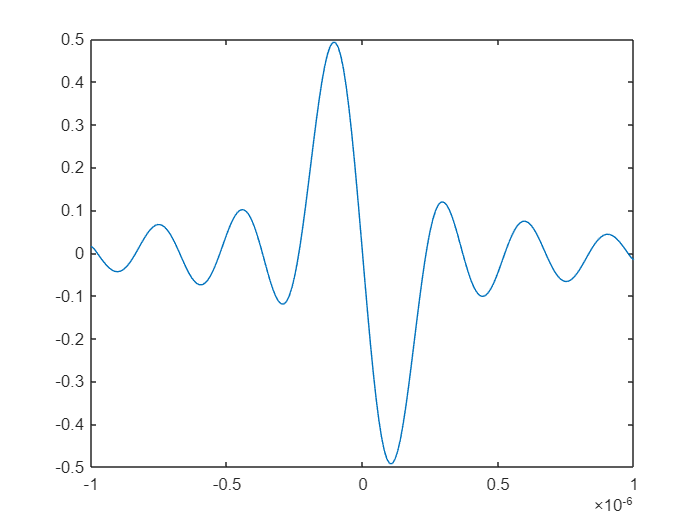


figure;plot(stepsize,scan_Fx);

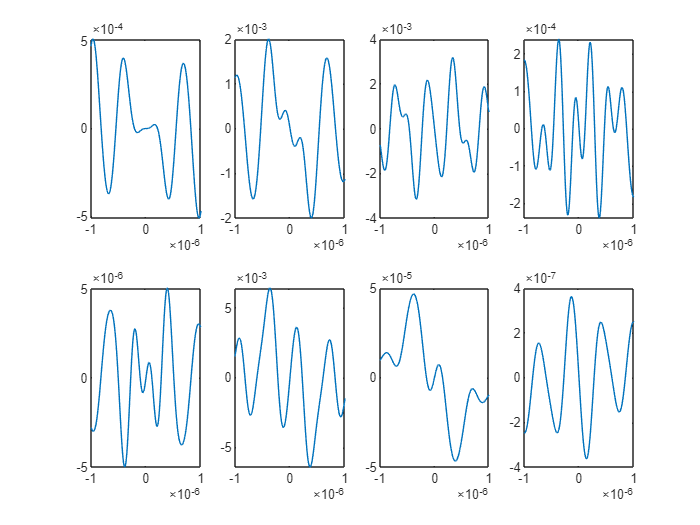


% 计算并绘制 8 项力及总力（y方向）
scan_F_grady = F_grady(center_sweep_line,:);
scan_F_rady = F_rady(center_sweep_line,:);
scan_F_vory = F_vory(center_sweep_line,:);
scan_F_curley = F_curley(center_sweep_line,:);
scan_F_curlhy = F_curlhy(center_sweep_line,:);
scan_F_spiney = F_spiney(center_sweep_line,:);
scan_F_spinmy = F_spinmy(center_sweep_line,:);
scan_F_flowy = F_flowy(center_sweep_line,:);
scan_Fy=Fy(center_sweep_line,:);

figure;title('y方向的8项分力');hold on
subplot(2,4,1);plot(stepsize,scan_F_grady);
subplot(2,4,2);plot(stepsize,scan_F_rady);
subplot(2,4,3);plot(stepsize,scan_F_vory);
subplot(2,4,4);plot(stepsize,scan_F_curley);
subplot(2,4,5);plot(stepsize,scan_F_curlhy);
subplot(2,4,6);plot(stepsize,scan_F_spiney);
subplot(2,4,7);plot(stepsize,scan_F_spinmy);
subplot(2,4,8);plot(stepsize,scan_F_flowy);

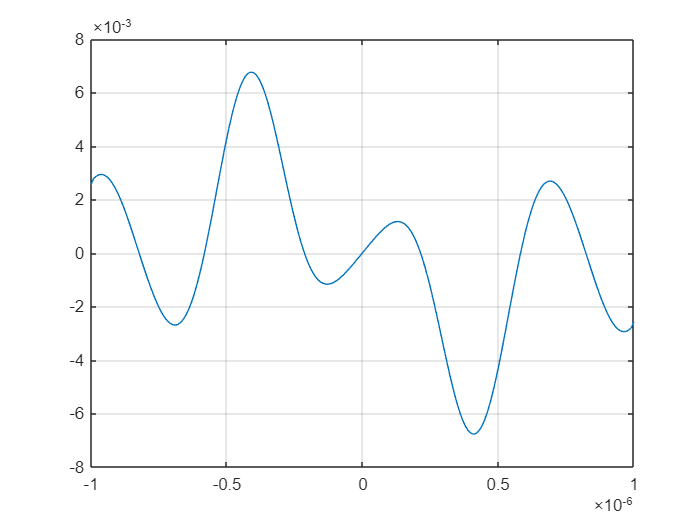

figure;plot(stepsize,scan_Fy);grid on;

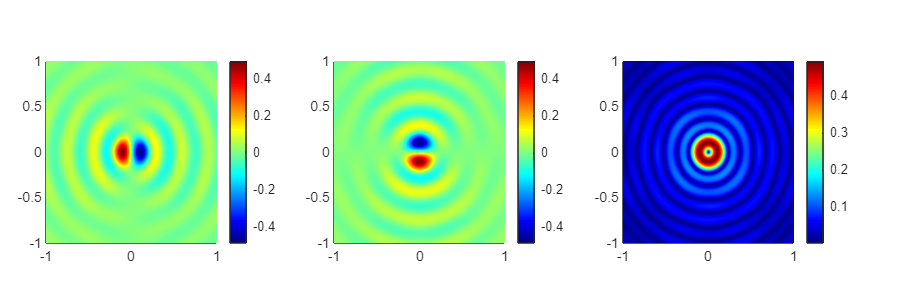

% 绘制平面受力图像
fig = figure('Name','受力图');
% 设置 figure 的大小
set(fig, 'Position', [500 100 900 300]);  % [left, bottom, width, height]

% 设置默认字体大小为 8
set(groot, 'DefaultAxesFontSize', 10);

ha = tight_subplot(1,3,[.1 .05],[.2 .2],[.05 .05]); 
% 上面参数对应：2行3列，间隔高宽，下上边缘，左右边缘

axes(ha(1));pcolor(xaxis,xaxis,Fx);colormap(gca,"jet");colorbar;shading interp
axes(ha(2));pcolor(xaxis,xaxis,Fy);colormap(gca,"jet");colorbar;shading interp
axes(ha(3));pcolor(xaxis,xaxis,Ftr);colormap(gca,"jet");colorbar;shading interp

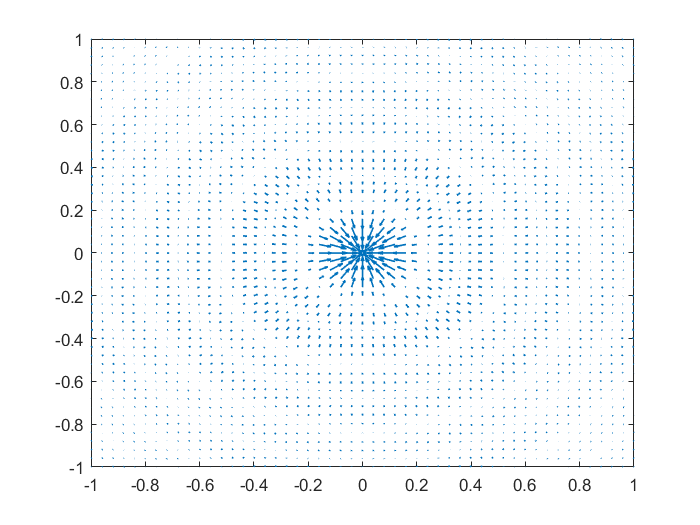

% 受力矢量图
[X,Y] = meshgrid(xaxis,xaxis);
dnum = 4;
figure('Name','受力矢量图');
% set(gcf,'Position',[100 100 450 400]);
q = quiver(matdimdown(X,dnum),matdimdown(Y,dnum),...
    matdimdown(Fx,dnum),matdimdown(Fy,dnum),...
    1.2,LineWidth=1);
xlim([-1 1]);
ylim([-1 1]);

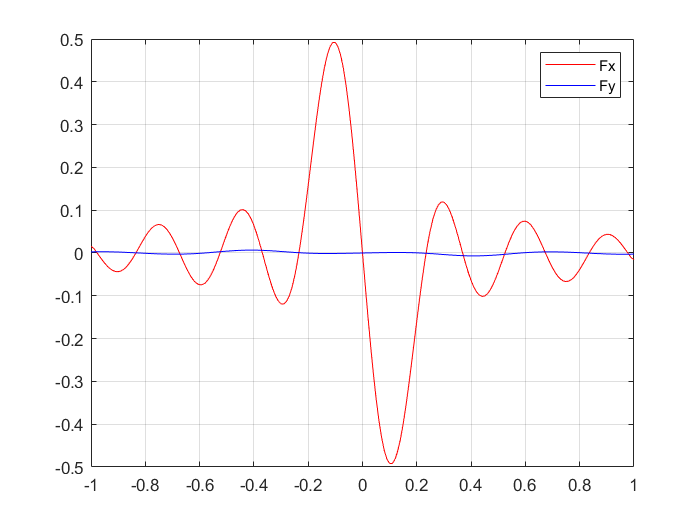

% 扫描线
scan_Fx = Fx(center_sweep_line,:);
scan_Fy = Fy(center_sweep_line,:);

figure('Name','sweepF');
plot(xaxis,scan_Fx,'Color','r');hold on
plot(xaxis,scan_Fy,'Color','b');
legend('Fx','Fy');grid on;


% figure('Name','坡印廷矢量');
% quiver(matdimdown(X,dnum),matdimdown(Y,dnum),...
%     matdimdown(Poyx,dnum),matdimdown(Poyy,dnum)); 
% xlim([-1 1]);
% ylim([-1 1]);
